Auteurs : JOHNSEN, Brage Floenaes et ORVIK, Oskar

Dans le cadre de CSLC on est demandé de stabiliser un robot sur deux roues. on va le stabiliser avec un correcteur PI.

Clear all pour faire un remise à nouveau

clear all

On déclare les paramètres physique du robot

% Parameters of the  two-wheel robot 

%Physical Constant
g = 9.81;						% gravity acceleration [m/sec^2]


%Lego Mindstorms EV3 Parameters
m = 0.03;						% wheel weight [kg] valor inicial 0.03
R = 0.042;						% wheel radius [m]  valor inicial 0.04
Jw = m * R^2 / 2;				% wheel inertia moment [kgm^2]
M = 0.67;						% body weight [kg]
W = 0.165;						% body width [m]
D = 0.05;						% body depth [m]
H = 0.152;						% body height [m]
L = H / 2;						% distance of the center of mass from the wheel axle [m]
Jpsi = M * L^2 / 3;				% body pitch inertia moment [kgm^2]
Jphi = M * (W^2 + D^2) / 12;	% body yaw inertia moment [kgm^2]
fm = 0.0022;					% friction coefficient between body & DC motor
fw = 0;							% friction coefficient between wheel & floor


%DC Motor Parameters

Jm = 1e-5;						% DC motor inertia moment [kgm^2]
Rm = 6.8327;					% DC motor resistance [��]
Kb = 0.468;						% DC motor back EMF constant [Vsec/rad]
Kt = 0.3047;					% DC motor torque constant [Nm/A]
n = 1;							% gear ratio

On continue avec le chargement des variables pour que des expressions qui suivent soient plus legères


$$\alpha = \frac {nK_t}{R_m} \\
\beta = \frac {nK_tK_b}{Rm} + fm \\
K = \frac {1}{\frac 1 2 m W^2+J_\phi+ \frac {W^2}{2R^2}(J_w+n^2)};$$


alpha = n*Kt/Rm;
beta = n*Kt*Kb/Rm + fm;
K = 1/(1/2*m* W^2+Jphi+W^2/(2*R^2)*(Jw+n^2));


$$On \ genère \ le \ système \ \dot x_2 : \\

\dot {x_2} = A_2 x_2 + B_2 u  \Leftrightarrow \\ 

\left[\matrix{ \dot \phi \cr \ddot \phi} \right] = \left[\matrix{ 0 & 1 \cr 0 & -\frac {W^2}{2R^2} \frac {\beta+f_w} {\frac {1}{2}mW^2 + J_{\phi} + \frac {W^2} {2R^2}}(J_w + n^2J_m)} \right] 

\left[\matrix{ \phi \cr \dot \phi} \right]  + \left[\matrix{ 0 & 0 \cr  -\frac 
{W} {2R} \alpha K & \frac {W}{2R} \alpha K} \right] \left[\matrix{ v_l \cr v_r} \right]$$


A_2 = [0, 1; 0, -(W^2)/(2*R^2)*(beta+fw)/(0.5*m*W^2 + Jphi + W^2/(2*R^2)*(Jw + n^2*Jm))]; 
B_2 = [0, 0; -W/(2*R)*alpha*K, W/(2*R)*alpha*K];
C_2 = eye(2);
D_2 = zeros(2);
sys2 = ss(A_2, B_2, C_2, D_2)

sys2 =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -75.78
 
  B = 
             u1        u2
   x1         0         0
   x2  -0.01135   0.01135
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



$$On \ genère \ les \ matrices \ E, \ F,\ G \ et \ H.
$$



$$E \left[\matrix{ \ddot \theta \cr \ddot \Psi} \right]  + F \left[\matrix{ \dot \theta \cr \dot \Psi} \right]  + G \left[\matrix{ \theta \cr \Psi} \right]  = H \left[\matrix{ v_l \cr v_r} \right] $$


En se basant sur les équations des forces on retrouve les matrices E, F, G et H.


$$
F_\theta = \alpha (v_l + v_r) - 2(\beta + f_w) \dot{\theta} + 2\beta \dot{\Psi} \\
F_\Psi = -\alpha (v_l + v_r) + 2\beta \dot{\theta} - 2\beta \dot{\Psi}  \\
F_\phi = \frac{W}{2R} \alpha (v_r - v_l) - \frac{W^2}{2R^2} (\beta + f_w) \dot{\phi}  \\

\alpha = \frac{n K_t}{R_m}, \\
\beta = \frac{n K_t K_b}{R_m} + f_m.
$$


E = [(2*m + M )*R^2 + 2*Jw + 2*n^2*Jm, M*L*R - 2*n^2*Jm; M*R*L - 2*n^2*Jm, M*L^2 + Jpsi+2*n^2*Jm];
F = [2*(beta + fw), -2*beta; -2*beta, 2 * beta];
G = [0, 0; 0, -M*g*L];
H = [alpha, alpha; -alpha, -alpha];

**3.1 - Système MIMO - Multiple Inputs Multiple Outputs**


$$On \ genère\ le\ model\ state \ space  \ \dot x_1: \\ 
\dot {x_1} = A_1 x_1 + B_1 u \\

\left[\matrix{ \dot \phi \cr \dot \psi \cr \ddot \phi \cr \ddot \psi} \right] = \left[\matrix{ 0 & 0 & 1 & 0 \cr 0 & 0 & 0 & 1 \cr -E^{-1}G &  & - E^{-1}F} \right] \left[\matrix{ \phi \cr \psi \cr \dot \psi \cr \dot \phi} \right] + \left[\matrix{ 0 & 0 \cr  0 & 0 \cr E^{-1}H} \right] \left[\matrix{ v_l \cr v_r} \right]
$$


A_1 = [0, 0, 1, 0; 0, 0, 0, 1; -inv(E)*G, -inv(E)*F];
B_1 = [0, 0; 0, 0; inv(E)*H];
C_1 = eye(4);
D_1 = zeros(4,2);
sys1 = ss(A_1, B_1, C_1, D_1)

sys1 =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -413.5  -131.6   131.6
   x4       0   265.6   62.73  -62.73
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3   127.2   127.2
   x4  -60.62  -60.62
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.


**3.2 Système SISO - Single Input Single Output**

On crée la version ajustée pour l'entrée pour l'entrée qui est égal pour les deux moteurs. Cela prends les valeurs de chaque ligne et les additionne.


$$u =\frac {v_l + v_r} 2$$


Alors, on fait la somme des valeurs dans la matrice de B.

B_1_Ajuste = sum(B_1, 2);

On prends l'hypothèse qu'il n'y a pas des liens directs entre l'entrée et la sortie.

On genère ce nouveau système et prends soin que tous les matrices sont de bonnes dimensions.

sys1_ajuste = ss(A_1, B_1_Ajuste, C_1, 0)

sys1_ajuste =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -413.5  -131.6   131.6
   x4       0   265.6   62.73  -62.73
 
  B = 
           u1
   x1       0
   x2       0
   x3   254.3
   x4  -121.2
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


On lance le réponse step, et on voit que ça diverge. Le système n'est donc pas stable en boucle ouverte.

Cela est également possible de voir avec les valeurs propres de la matrice A, tel que il y a des poles de partie réelle positive.

Val_Propre1 = eig(A_1)

Val_Propre1 =          0
 -195.4283
    7.3730
   -6.2499


On voit qu'on a un pôle en 7, qui a une partie réelle positive, et un pôle en 0 qui est asymptotiquement stable. Ces pôles engendrent une instabilité au système.

**4 - Simulation en Simulink**

On a crée un modèle dans Simulink, qui utilise les matrices dans le script.

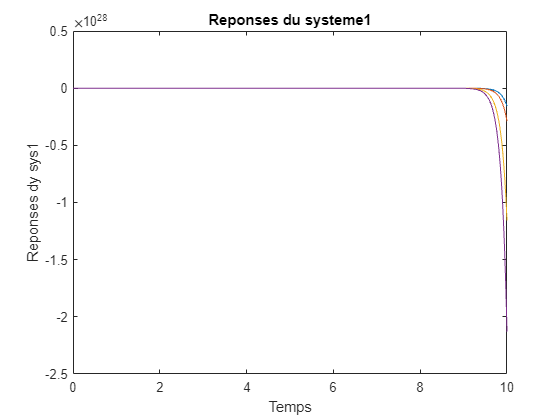

D_1_Ajuste = zeros(4,1);
sys1_output = sim("System1Ajuste.slx");
plot(sys1_output.tout, sys1_output.simout.Data);
xlabel('Temps');
ylabel('Reponses dy sys1');
title('Reponses du systeme1')

On fait un petit zoom sur la réponse du système

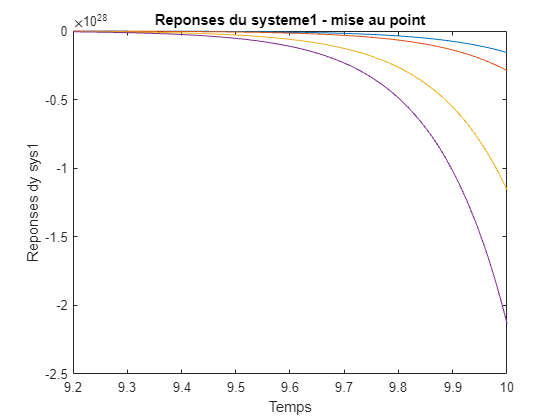

figure()
plot(sys1_output.tout, sys1_output.simout.Data);
xlabel('Temps');
ylabel('Reponses dy sys1');
title('Reponses du systeme1 - mise au point')
xlim([9.2,10]);

**4 - Réponse d'échelon**

Après, on vérifie cette instabilité avec une réponse de step, une entrée d'un échelon. On voit que la sortie diverge.

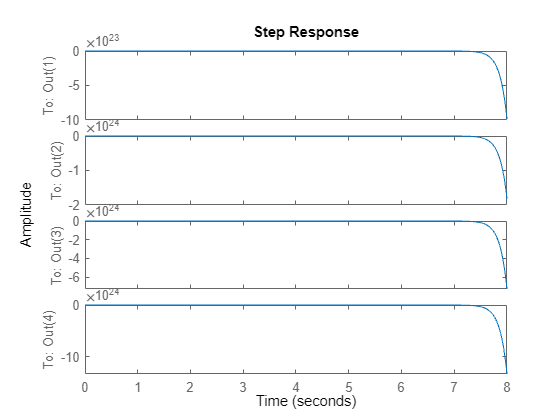

step(sys1_ajuste);

**4 - Réponse d'impusion**

On voit le même résultat avec un entrée d'impulsion.

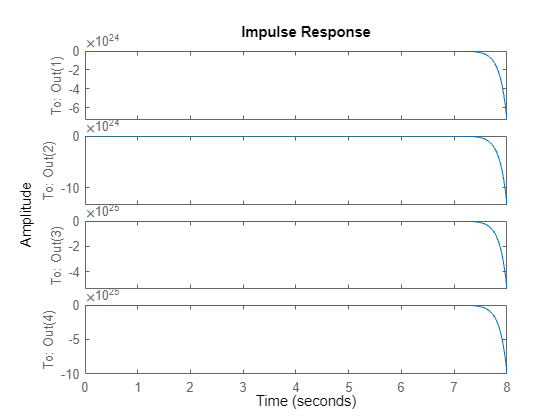

impulse(sys1_ajuste)

On voit qu'avec des différentes valeurs de proportionelle, le système reste instable. On verra le même résultat plus tard.

**5 - Analyse observailité et commandabilité **

On cherche ensuite à étudier l'observabilité et commandabilité du systeme.

Pour cela on crée les matrices de commandabilité et observabilité :


$${Q_c1} = \left[\matrix{ B_1 & A_1B_1 & ... & A_1^{n-1}B_1} \right] \\
{Q_o1} = \left[\matrix{ C_1 \cr C_1 A_1 \cr ... \cr C_1 A_1 ^{n-1}} \right]
$$


Q_c = [B_1_Ajuste, A_1*B_1_Ajuste, A_1^2*B_1_Ajuste, A_1^3*B_1_Ajuste];
RangQc = rank(Q_c)

RangQc = 4

On voit que le rang de la matrice de commandabilité est bien 4, qui est l'ordre du système.

Ceci est une nécessité de la commandabilité du système. Donc le système est bien commandable.

Q_o = [C_1; C_1*A_1; C_1^2*A_1; C_1^3*A_1];
RangQo = rank(Q_o)

RangQo = 4

On voit que le rang de la matrice d'observabilité est bien 4, qui est l'ordre du système.

Ceci est une nécessité de la commandabilité du système. Donc le système est bien commandable.

Kp = linspace(0.1,10,10); % Pour ploter
G = tf(sys1_ajuste)

G =
 
  From input to output...
        254.3 s^2 + 9.036e-13 s - 1.741e04
   1:  ------------------------------------
       s^4 + 194.3 s^3 - 265.6 s^2 - 9006 s
 
             -121.2 s + 4.546e-14
   2:  --------------------------------
       s^3 + 194.3 s^2 - 265.6 s - 9006
 
       254.3 s^2 + 4.518e-13 s - 1.741e04
   3:  ----------------------------------
        s^3 + 194.3 s^2 - 265.6 s - 9006
 
       -121.2 s^2 + 4.546e-14 s - 1.46e-30
   4:  -----------------------------------
        s^3 + 194.3 s^2 - 265.6 s - 9006
 
Continuous-time transfer function.


On se focalise sur la fonction de transfert numéro 1, parce que l'évolution de l'angle est décrit par cette fonction, celle qu'un va pouvoir contrôler.

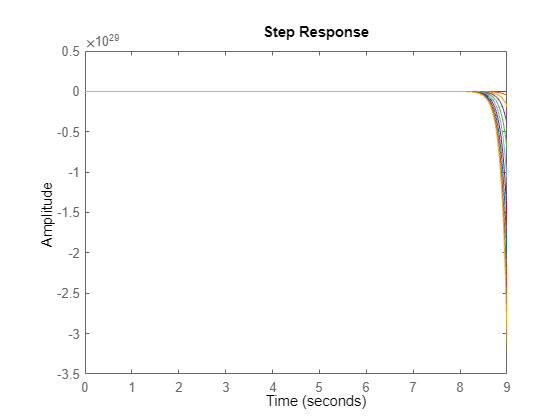

Poles = [4,length(Kp)];
figure;
hold on;
for i = 1:length(Kp)
    KP = Kp(i);
    T = feedback(KP * G(1,1),1);
    step(T)
    % Enlever les pourcentages pour montrer les pôles pour des 
    % coéfficients proportionelles différentes
    %print("Les pôles pour Kp = %d :", Kp(i));
    %pole(T)
end
hold off;

**6 - Pôles et zéros dans le plan de Laplace**

On plot les pôles dans le plan complex avec la fonction "root locus"

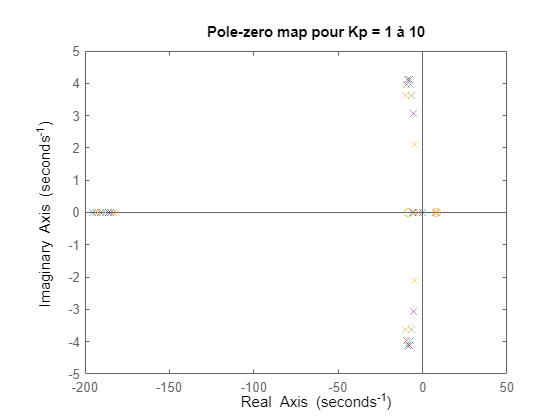

figure()
hold on
for i = 1:length(Kp)
    KP = Kp(i);
    T = feedback(KP * G(1,1),1);   
    pzmap(T)
end
title("Pole-zero map pour Kp = 1 à 10")
hold off;

Ici, on voit que les pôles et zéros du système en évoluant le coéfficient proportionelle, Kp.

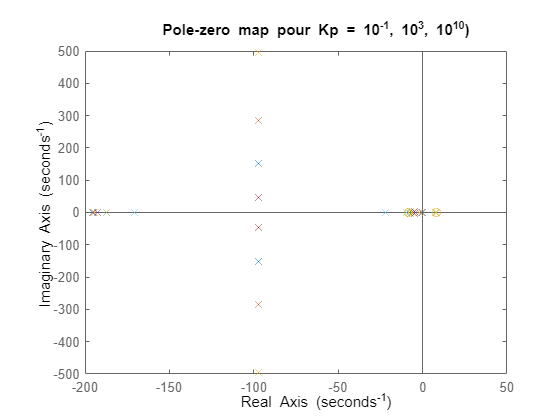

Kp = logspace(-1, 3, 10);
figure;
hold on;
for i = 1:length(Kp)
    KP = Kp(i);
    T = feedback(KP * G(1,1),1);
    pzmap(T)
end
title("Pole-zero map pour Kp = 10^{-1}, 10^3, 10^{10})")
hold off;

damp(G(1, 1))

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -6.25e+00     1.00e+00       6.25e+00         1.60e-01    
  7.37e+00    -1.00e+00       7.37e+00        -1.36e-01    
 -1.95e+02     1.00e+00       1.95e+02         5.12e-03    


**6 - Evolution des pôles pour tous les valeurs du correcteur proportionelle**

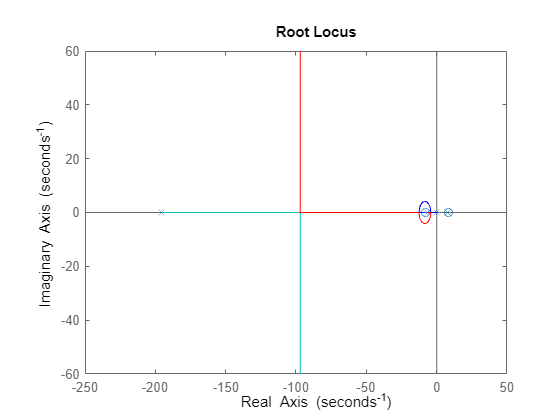

figure;
rlocus(G(1, 1))

Conclusion :

Avec n'importe lequel proportionel, on ne peut jamais obtenir la stabilité.

C'est à cause de cela qu'on passe sur un controlleur PI.

**6.2 - Correcteur PI**

On souhaitons appliquer la loi de commande suivante :


$$u = (K_p + K_i\frac 1 p) \epsilon
$$


On trouve le polynôme characteristique de l'angle theta en boucle ouverte.


$$P(s) = s^4 +194,3 s^3 - 265.6 s^2 -9005.6s
$$


PolyCaracteristique = G(1, 1).Denominator{1, 1};

**6.3 - State feedback**

On définit les coéfficients de l'équation characteristique 

a4 = PolyCaracteristique(1);
a3 = PolyCaracteristique(2);
a2 = PolyCaracteristique(3);
a1 = PolyCaracteristique(4);
a0 = PolyCaracteristique(5);

b1 = (a3*a2-a4*a1)/a3;
b2 = (a3*a0 - a4*0)/a3; b2 = 0;
c1 = (b1*a1 - a3*b2)/b1;
c2 = (b1*0 - a3*0)/b1; c2 = 0;

Routh = [a4, a2, a0;
         a3, a1, 0;
         b1, b2, 0;
         c1, c2, 0]

Routh = 1.0e+03 *

    0.0010   -0.2656         0
    0.1943   -9.0056         0
   -0.2192         0         0
   -9.0056         0         0


Comme les valeurs de la première colonne n'ont pas tous la même signe, alors le système n'est pas stable.

Cependant, le système est commandable. C'est donc possible de le rendre stable.

On cherche à corriger ce système avec un correcteur, tel qu'on aura un temps de reponse de 0.7s et un depassement de 5%.


$$t_r = \frac 4 {(\zeta w_n)} \\
D = e^{(\frac{-\pi \zeta} {\sqrt{1-\zeta^2}})}
$$


En utilisant ces deux equations on trouve que


$$\zeta = 0.69 \\ w_n = 8.28 \ \frac {rad} s$$


On aura donc un système d'ordre 2:


$$\phi_1(s) = s^2 + 11.43s + 68.56$$


Cela est le système qu'on veut être dominante sur le système final.

Mais ce système n'est pas d'ordre 4 comme notre sytème de depart, donc on ajoute deux pôles non-dominante, donc au gauche des pôles existantes dans le plan de Laplace.

On aura donc:


$$\phi(s) = (s^2 + 11.43s + 68.56)(s + 30)(s + 40)$$


tr_list = [0.5:0.05:1] % Liste des temps de réponse

tr_list =     0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000


dep = 0.05;
tr = tr_list(5);
z = sqrt((log(dep)^2) / (pi^2 * (1 + log(dep)^2/pi^2)));
wn = 4/(tr*z);
coeff1 = 1;
coeff2 = 2*wn*z;
coeff3 = wn^2;
Racines = roots([coeff1, coeff2, coeff3]);


Notre ploynôme characteristique de la boucle fermé avec correcteur aura la forme:

$P_{BF} = \det(sI - A + BK)$, tel que K est une matrice (1,4) de notre correcteur. Et on sait déjà que le système est commandable.

La fonction transfert pour $\theta
$:


$$G(s) =
\frac { 
       254.3 s^2 + 9.036 \cdot 10^{-13} s - 1.741 \cdot 10^{-4}}
       {s^4 + 194.3 s^3 - 265.6 s^2 - 9006 s}$$


Ces sont les coefficient de l'équation characteristique de la boucle ouverte.


$$Cela \ est \ le \ P(s) = a_0 + a_1 s + ... + a_{n-1} \ s^{n-1} + s^n$$


Den = G(1).denominator{1};
a0 = Den(5);
a1 = Den(4);
a2 = Den(3);
a3 = Den(2);

A1_Comm = [0, 1, 0, 0; 0, 0, 1 ,0; 0, 0, 0, 1; 0, 9006, 256.6, -194.3]% La matrice de campagne du systeme de base

A1_Comm = 1.0e+03 *

         0    0.0010         0         0
         0         0    0.0010         0
         0         0         0    0.0010
         0    9.0060    0.2566   -0.1943


roots([1 11.43 68.6])

ans =   -5.7150 + 5.9949i
  -5.7150 - 5.9949i


Ceci sont les pôles du système avec les proprietés souhaitaient.


p_des = [Racines(1), Racines(2),-5.8,-5.9]

p_des =   -5.7143 + 5.9925i  -5.7143 - 5.9925i  -5.8000 + 0.0000i  -5.9000 + 0.0000i


On mets deux pôles à côté des deux pôles trouvés précedemment.

Ces sont les coefficients de l'équation characteristique désirée, qui satisfait les conditions voulu, par rapport aux conditions qu'on est données, notemment overshoot et temps de réponse.


$$Cela \ est \ le \ \Psi(s) =  \alpha_0 + \alpha_1 s + ... + \alpha_{n-1} \ s^{n-1} + s^n$$


Poly_des = poly(p_des);

Ceci donne l'équation characteristique final pour l'angle theta en boucle fermé avec un correcteur PI:


$$P_{final} = s^4 + 22,9s^3 + 233.1s^2 + 1166,3s + 2266,7
$$


On construit la matrice de compagne :

A1_Comm_Des = [0, 1, 0, 0; 0, 0, 1 ,0; 0, 0, 0, 1; -Poly_des(5), -Poly_des(4), -Poly_des(3), -Poly_des(2)] % Matrice de compage

A1_Comm_Des = 1.0e+03 *

         0    0.0010         0         0
         0         0    0.0010         0
         0         0         0    0.0010
   -2.3462   -1.1933   -0.2365   -0.0231


On soustrait les coefficients de l'équation characteristique voulu avec celle de base et on peut utiliser la fonction place() pour comparer.


$$K_i = \alpha_i - a_i$$


K_d = place(A_1,B_1_Ajuste,p_des)

K_d =    -0.1348   -4.4236   -0.5859    0.1828


eig(A_1-B_1_Ajuste*K_d)

ans =   -5.7143 + 5.9925i
  -5.7143 - 5.9925i
  -5.8000 + 0.0000i
  -5.9000 + 0.0000i


On devrait trouver les matrices de compagne avec la matrice de changement de base, M.

m4 = B_1_Ajuste;
m3 = (A_1 + a3*eye(4))*B_1_Ajuste;
m2 = (A_1^2 + a3*A_1 + a2 * eye(4))*B_1_Ajuste;
m1 = (A_1^3 + a3*A_1^2 + a2*A_1 + a1 * eye(4))*B_1_Ajuste;
M = [m1, m2, m3, m4]

M = 1.0e+04 *

   -1.7408    0.0000    0.0254         0
    0.0000   -0.0000   -0.0121         0
    0.0000   -1.7408    0.0000    0.0254
   -0.0000    0.0000   -0.0000   -0.0121


Az = inv(M)*A_1*M

Az = 1.0e+03 *

   -0.0000    0.0010    0.0000    0.0000
   -0.0000    0.0000    0.0010    0.0000
    0.0000   -0.0000   -0.0000    0.0010
   -0.0000    9.0056    0.2656   -0.1943


K_tilde = A1_Comm_Des(4,:) - A1_Comm(4,:)

K_tilde = 1.0e+04 *

   -0.2346   -1.0199   -0.0493    0.0171



$$En \ utilisant \ le \ fait \ que \ Mz =x \\
On \ trouve \ K \ avec \ :
K = - \tilde{K}M^{-1}
$$


K = -K_tilde*inv(M)

K =    -0.1348   -4.3496   -0.5859    0.1827


En comparant avec la fonction place, on voit que les coéfficients sont les mêmes.

G_0 = C_1*inv(-A_1+B_1_Ajuste*K)*B_1_Ajuste % Gain statique

G_0 =    -7.4194
         0
         0
         0


lc = (pi/5) /G_0(1)

lc = -0.0847

lc_corr = 8.23*0.6/(-1.74*10^-4)

lc_corr = -2.8379e+04

corri = 1/0.6

corri = 1.6667


$$G(0) = C(-A+BK)^{-1}  l_c = \frac \pi 5 $$



$$Donc \ on \ trouve \ l_c = 2.9713$$



$$Il \ faut \ trouver \ le \ l_c \ corrigé \\
\dot x = (A-BK) x + Bl_cy_c \\
\dot x = Ax + Bu \\
u(t) = -Kx(t) + l_cy_c(t)\\
y^* = y_c^* \\ 
\dot x = 0 \Leftrightarrow x^* = -(A-BK)^{-1}Bl_cy_c^* \\
y^* = -C(A-BK)^{-1}Bl_cy_c^* \\
Donc: \\
1/l_c = -C(A-BK)^{-1}B\\
l_c = -4.729\\
$$
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

Lc_corrige_inv = -C_1*(inv(A_1-B_1_Ajuste*K))*B_1_Ajuste

Lc_corrige_inv =    -7.4194
         0
         0
         0


Lc_corrige = 1/(Lc_corrige_inv(1,1))

Lc_corrige = -0.1348

On fait une simulation avec simulink

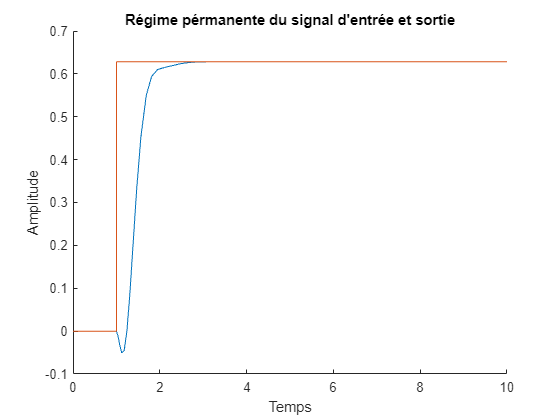

SimFinal = sim("StateFeedbackK.slx");
figure()
hold on;
plot(SimFinal.logsout{1}.Values.Time, SimFinal.logsout{1}.Values.Data);
plot(SimFinal.logsout{2}.Values.Time, SimFinal.logsout{2}.Values.Data)
title("Régime pérmanente du signal d'entrée et sortie")
xlabel("Temps")
ylabel("Amplitude")

On voit un petit "undershoot", avant que le système se stabilise. 

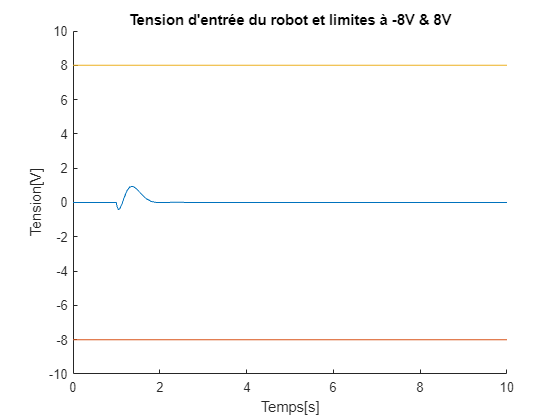

figure()
hold on
plot(SimFinal.logsout{3}.Values.Time, SimFinal.logsout{3}.Values.Data)
plot(SimFinal.logsout{3}.Values.Time, -8*ones(1, length(SimFinal.logsout{3}.Values.Time)))
plot(SimFinal.logsout{3}.Values.Time, 8*ones(1, length(SimFinal.logsout{3}.Values.Time)))
ylim([-10, 10])
title("Tension d'entrée du robot et limites à -8V & 8V")
xlabel("Temps[s]");
ylabel("Tension[V]")
hold off

On a essayé avec un temps de réponse de 0.5 s, et on voit que le tension passe en-dessous de -8V.

Avec un temps de réponse de ~0.55 s, on est très proche de la limite de ce que le moteur supporte comme entrée. Donc, on peut se permettre de passer de 0.7s à 0.55 s pour que le système aille plus vite. 

Pour générer postions et simtime, on lance NXTwaySim en Simulink.

Après, on fait un test pour voir le comportement du systeme.

sim NXTwaySim.slx
%playAnimation(positions,simtime)

**8 - Conclusion**

Avec ce projet, on a vu le placement des pôles, et l'impact de nos choix sur la performance du système.

On a vu théoriquement et avec un logiciel, comment les selectionner.

On a vérifié le commandabilité et observabilité, en utilisant les notions vu en cours, qui est primordial pour tout changement du système.

Les outils MATLAB nous a fait rendu compte qu'un correcteur P ne suffisait pas, et qu'il fallait passer à un correcteur PI.

L'outil Simulink, une partie en MATLAB, nous a permis de découvrir le "state controller", qui était des dessins dans la polycopie. Avec le logiciel, ces diagrammes ont pris vie et nous a autorisé de voir l'impact des gains différents sur le scope.

Enfin, la simulation nous a permis de voir que nôtre travail a abouti dans une stabilité.